# Balanced Fund Data File

**Author: Nina Matthews**

**Project: Masters Dissertation - Blending Mean-Variance and Hierarchical Risk Parity using Time- and Market-Conditioned Flexible Probabilities**

**Last edit: 19/05/2023**

**Supervisor: A/Prof. Tim Gebbie**

**Resources Used: **The MathWorks, Inc. (2019) 

#### **Needed Data: **

#### ASSET Px_Last

"DATA-PROCESSED-SIG-PX_LAST-M-TTABLE-20000229-20230228.mat"

#### Signal Px_Last

"DATA-PROCESSED-SIG-PX_LAST-M-TTABLE-20000229-20230228.mat"

## **Purpose**

*****

*****

*****

## **1. Environment Setup **

**Clear Env and Plots**

clc % clear command window
close all %clear all figs
clear % clears workspace

**Source Directories **

Set path for processed data

% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/'));

**Export Directories**

Set Image export path:

% use your default user path to create the filename and path
exportName = '';
imageExportpath = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Data Manipulation/',exportName);

Set Output data EXPORT path

dataExportpath = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/', exportName);

## 2. Load Test Data: ASSET Log Dif Returns & Sig Data

**Set Directories & Load Data**

Load Processed Signal and Asset Class data

% use your default user path to create the filename and path
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/'))
load 'DATA-PROCESSED-SIG-PX_LAST-M-TTABLE-20000229-20230228.mat';
load 'DATA-PROCESSED-ASSETCL-PX_LAST-M-TTABLE-20070630-20230228.mat';

% Extract the market and cash columns
columnsToExtract = {'JALSHTR_Index', 'JIBA3M_Index'};
Mrkt_CashTT = SIG_aligned_dataTable(:, columnsToExtract);
% Combine the timetables
BALFUN_TT = synchronize(Mrkt_CashTT, ASSETCL_TableFilled);

Here we see that it's only missing data at the start and not inbetween. 

Create plot names (excludes the underscore)

% rename the variables with underscores instead of spaces
ASSETCL_PlotNames = strrep(BALFUN_TT.Properties.VariableNames, '_', ' ');
% remove the 'TR' the variables with underscores instead of spaces
ASSETCL_PlotNames = strrep(ASSETCL_PlotNames, 'TR', '');

% missing data to plot in array
tickers = BALFUN_TT.Properties.VariableNames;
na_array = transpose(isnan(table2array(BALFUN_TT)));
ax = axes;

spy(na_array, 'black-',5);
set(gca,'ytick',1:5,'yticklabel',ASSETCL_PlotNames);
pbaspect([8 6 1]);
ylabel("Assets");
xlabel("Date Index");
title("Missing Data");
BalancedF_NAplot = gca;
 close all

**Export NA Data plot**

exportName = 'BalancedF_NAdata_plot.pdf'
exportgraphics(BalancedF_NAplot,fullfile(imageExportpath,exportName),'Resolution',300)

**Remove NA:** 

We currently have 23 yrs of data, however, 15 yrs of historical data should suffice, therefore we can drop the dates prior to the initial existance of all indices:

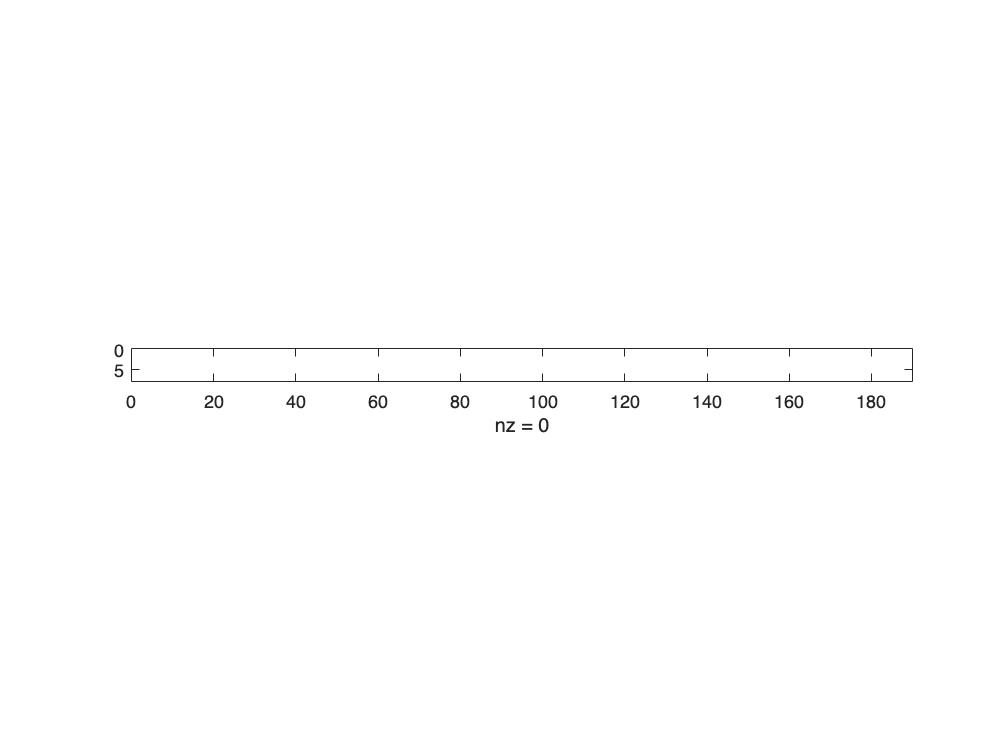

[countNans,idx] = max(sum(isnan(BALFUN_TT{:,:}),1));
rmmissingProxy =  BALFUN_TT.Properties.VariableNames{idx};
BALFUN_TT = rmmissing(BALFUN_TT,"DataVariables",rmmissingProxy);
spy(transpose(isnan(table2array(BALFUN_TT))))

**SAVE Processed Balanced Fund Datasets:**

exportName = 'DATA-PROCESSED-BALFUN-PX_LAST-M-TTABLE-20070630-20230228.mat';
save(fullfile(dataExportpath,exportName),'BALFUN_TT');

## 3. Invariant Prep

%rename the variables with underscores instead of spaces
BALFUN_PlotNames = strrep(BALFUN_TT.Properties.VariableNames, '_', ' ');
% remove the 'TR' the variables with underscores instead of spaces
BALFUN_PlotNames = strrep(BALFUN_PlotNames, 'TR', '');

### 3.1 **Normalize ** the TRI series to have the first index value of each asset equal to  

This creates a comparative wealth series for each asset over the time period.

% Divide each element in each column of x by the first element of that column
BALFUN_normalised_array = table2array(BALFUN_TT) ./ table2array(repmat(BALFUN_TT(1,:),height(BALFUN_TT),1));

% Convert the normalised array back to a timetable with the same timestamps as x
BALFUN_normalised = array2timetable(BALFUN_normalised_array, 'RowTimes', BALFUN_TT.Dates);

% Copy the column names from x to x_normalised
BALFUN_normalised.Properties.VariableNames = BALFUN_TT.Properties.VariableNames;

assetnames = BALFUN_normalised.Properties.VariableNames;
% Plot all asset normalised TRIs on a single plot
plot(BALFUN_normalised.Time, table2array(BALFUN_normalised));
ylabel("Normalised TRIs");
xlabel("Time");
title("Monthly Normalised Wealth Series From TRIs");
% include the legend
legend(BALFUN_PlotNames,Location="northwest");
BALFUN_norm_plot = gca;
hold off;

**Export Normalized Asset Class Wealth Series From TRIs Data plot**

exportName = 'BALFUN_norm_plot.pdf';
exportgraphics(BALFUN_norm_plot,fullfile(imageExportpath,exportName),'Resolution',300);

### 3.2 Calculate the Log Prices Series

% Log all columns of x and return as a new timetable object
lg_BALFUN = varfun(@(BALFUN_normalised) log(BALFUN_normalised), BALFUN_normalised, ...
    'OutputFormat', 'timetable');

% Copy the metadata from ASSETCL_normalised to lg_ASSETCL
lg_BALFUN.Properties.Description = BALFUN_normalised.Properties.Description;
lg_BALFUN.Properties.VariableDescriptions = BALFUN_normalised.Properties.VariableDescriptions;
lg_BALFUN.Properties.VariableNames = BALFUN_normalised.Properties.VariableNames;

% Plot all asset log(normalised TRIs) on a single plot
plot(lg_BALFUN.Time, table2array(lg_BALFUN));
ylabel("log(price)");
xlabel("Time");
title("Monthly Log Prices Series");
% include the legend
legend(BALFUN_PlotNames,Location="northwest");
BALFUN_logP_plot = gca;
hold off

**Export Log Price Plot**

exportName = 'BALFUN_logP_plot.pdf';
exportgraphics(BALFUN_logP_plot,fullfile(imageExportpath,exportName),'Resolution',300);

### 3.3 Calculating Log Price Differencing to first order of all Asset Classes  (create fn later)

% Calculate the log differences of all columns
BALFUN_array = table2array(BALFUN_TT);
BALFUN_log_array = log(BALFUN_array);
BALFUN_log_diff_array = diff(BALFUN_log_array);

% Create a new timetable object with the log differences
BALFUN_log_diff = array2timetable(BALFUN_log_diff_array, 'RowTimes', BALFUN_TT.Dates(2:end));

% Copy the metadata from ASSETCL_TableFilled to ASSETCL_log_diff
BALFUN_log_diff.Properties.Description = BALFUN_TT.Properties.Description;
BALFUN_log_diff.Properties.VariableDescriptions = BALFUN_TT.Properties.VariableDescriptions;
BALFUN_log_diff.Properties.VariableNames = BALFUN_TT.Properties.VariableNames;

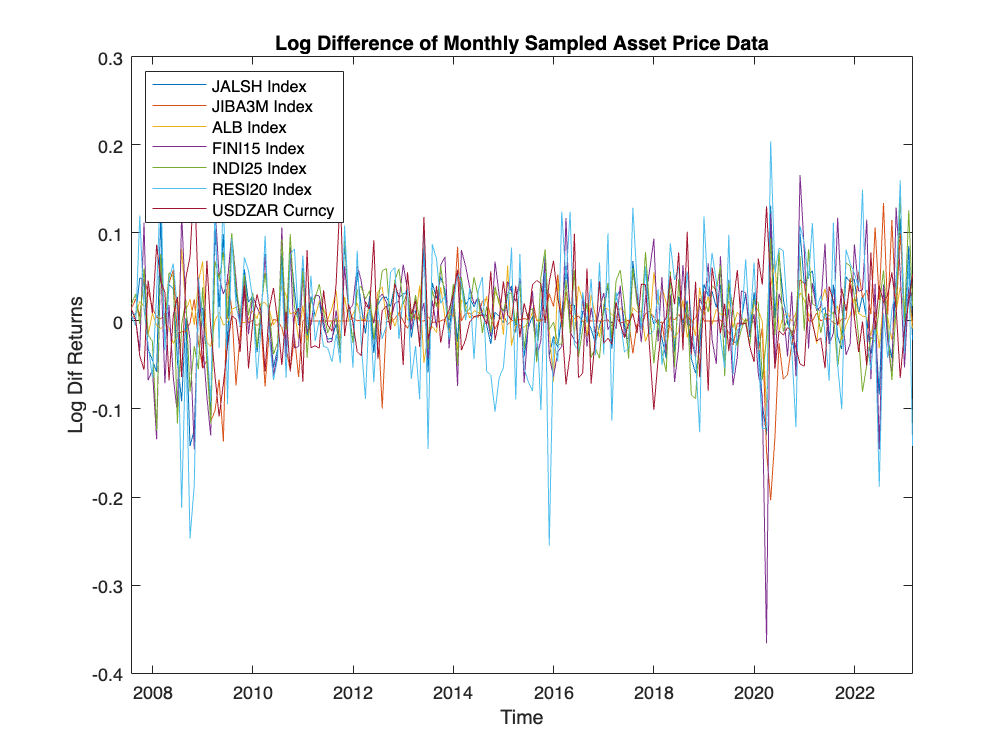

% Plot all asset log(normalised TRIs) on a single plot
plot(BALFUN_log_diff.Time, table2array(BALFUN_log_diff))
ylabel("Log Dif Returns")
xlabel("Time")
title("Log Difference of Monthly Sampled Asset Price Data")
% include the legend
legend(BALFUN_PlotNames,Location="northwest");
BALFUN_logDifRet_plot = gca;
hold off;

#### **Export Log Diff Returns Plot**

exportName = 'BALFUN_logDifRet_plot.pdf';
exportgraphics(BALFUN_logDifRet_plot, ...
    fullfile(imageExportpath,exportName),'Resolution',300);

#### **SAVE Log Diff Returns Datasets:**

**TO DO: Use data_cleaning_001 to auto assign date range to file names (will code later)**

% % Convert the start and end dates to strings in the desired format (YYYYMMDD)
% startDateStr = datestr(ASSETCL_log_diff.Properties.StartTime, 'yyyymmdd');
% endDateStr = datestr(ASSETCL_log_diff.Properties.EndDate, 'yyyymmdd');
% 
% % Generate the file name
% fileName = sprintf('DATA-PROCESSED-INVARIANT-LOGDIFRETURNS-M-TTABLE-%s-%s.mat', startDateStr, endDateStr);
% 
% % Save the timetable object using the generated file name
% % save(fileName, 'timetableObj');

% 
exportName = 'DATA-PROCESSED-BALFUN_INVARIANT-LOGDIF_RETURNS-M-TTABLE-20070731-20230228.mat';
save(fullfile(dataExportpath,exportName),'BALFUN_log_diff');

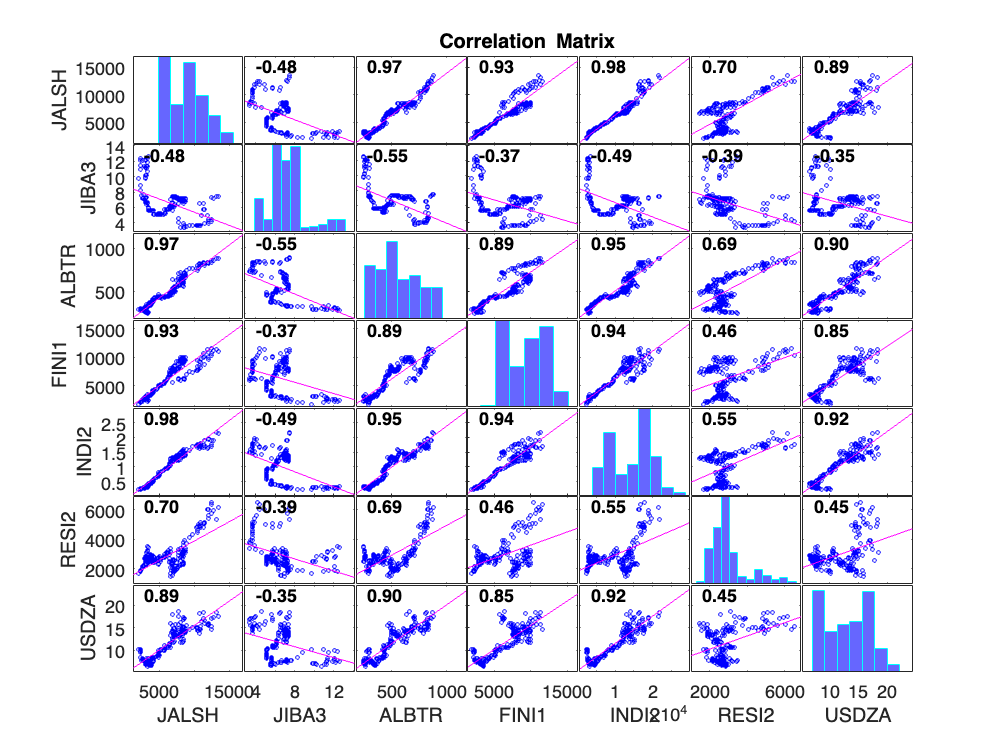

R = 7×7 table
              JALSH       JIBA3       ALBTR       FINI1       INDI2       RESI2      USDZA  
             ________    ________    ________    ________    ________    _______    ________

    JALSH           1    -0.47951     0.97349     0.92976     0.97636    0.70004     0.88749
    JIBA3    -0.47951           1    -0.54643    -0.36844    -0.48814    -0.3924    -0.35327
    ALBTR     0.97349    -0.54643           1     0.88837     0.95113    0.68939     0.89547
    FINI1     0.92976    -0.36844     0.88837           1     0.93815    0.45859      0.8465
    INDI2     0.97636    -0.48814     0.95113     0.93815           1    0.54951     0.92352
    

PValue = 7×7 table
                JALSH         JIBA3          ALBTR         FINI1          INDI2         RESI2         USDZA   
             ___________    __________    ___________    __________    ___________    __________    __________

    JALSH              1    2.9351e-12    9.1984e-122    4.4299e-83    2.3649e-126    3.7231e-29     7.905e-65
    JIBA3     2.9351e-12             1     4.1828e-16    1.8248e-07      1.042e-12    2.3452e-08     6.157e-07
    ALBTR    9.1984e-122    4.1828e-16              1    3.9559e-65     2.2738e-97    5.4851e-28    1.2022e-67
    FINI1     4.4299e-83    1.8248e-07     3.9559e-65             1     4.5104e-88    3.2233e-11    4.3919e-53
    

% pairwise Pearson correlations. 
% Pvals to test correlations are significant, alpha = 5% level
[R,PValue] = corrplot(BALFUN_TT)

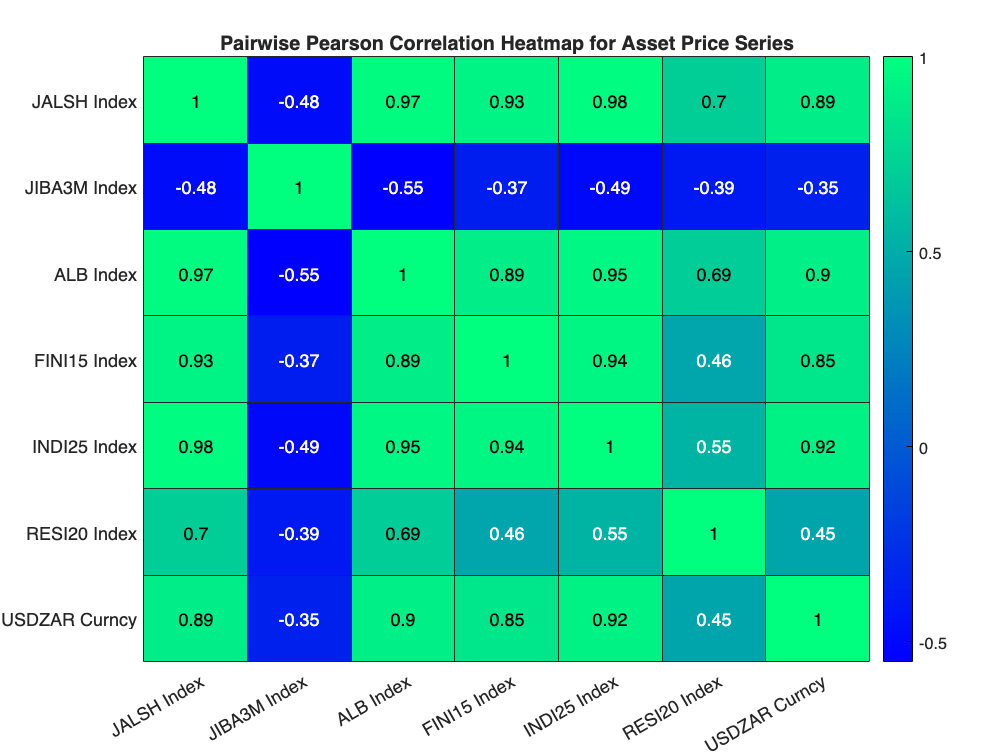

AssetCorr = round(corr(BALFUN_normalised_array),2);
h = heatmap(BALFUN_PlotNames,BALFUN_PlotNames,AssetCorr, 'Colormap',winter(200));
h.Title = 'Pairwise Pearson Correlation Heatmap for Asset Price Series';

#### **Export Log Diff Returns Plot**

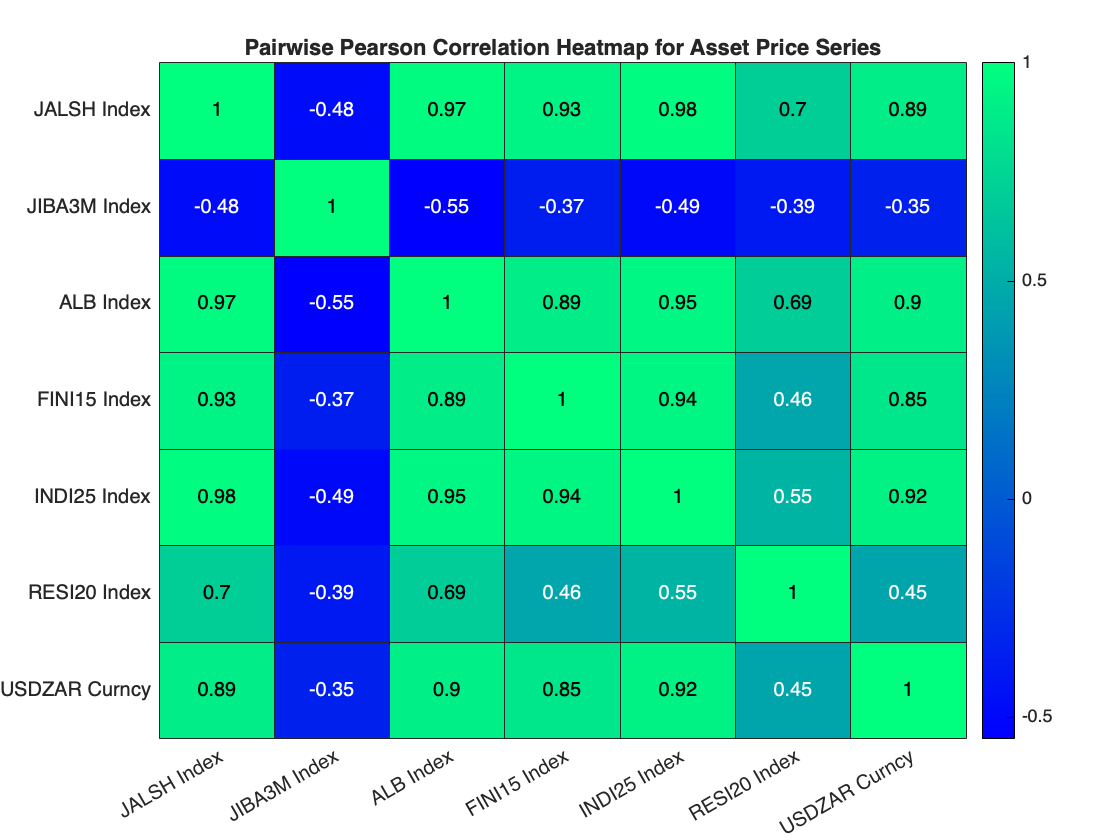

exportName = 'BALFUN_corr_heatmap.pdf';
exportgraphics(h, ...
    fullfile(imageExportpath,exportName),'Resolution',300);

### 3.4 Check for normal distribution of returns 

#### 3.4.1 PP Theoritical Distribution Plot

Plot PP and QQ-plots to see if log diff data is roughly normally distributed

probplot(table2array(BALFUN_log_diff));
legend(BALFUN_PlotNames,Location="northwest");
title("PP Plot of Log Difference of Price Against Theoretical Normal Distribution");
xlabel("Log Difference of Monthly Samples Asset Price Data")
grid on; % Add grid

% Adjust grid line properties
grid(gca, 'minor');
ax = gca;
ax.GridAlpha = 0.3; % Set grid transparency
ax.MinorGridAlpha = 0.25; % Set minor grid transparency

BALFUN_logDifRet_PP_plot = ax;
hold off;

**Export PP plot of ASSET Class log diff returns**

exportName = 'ASSETCL_logDifRet_PP_plot.pdf';
exportgraphics(BALFUN_logDifRet_PP_plot, ...
    fullfile(imageExportpath,exportName),'Resolution',300);

#### 3.4.2 PP Plot inset into QQ Plot for Log Returns

% Create main plot
figure;
qqplot(table2array(BALFUN_log_diff));
ylabel("Quantiles of Log Returns");
title("QQ Plot of Log Returns of Assets vs. Standard Normal");
legend(BALFUN_PlotNames, "Location", "northwest");
grid on; % Add grid

% Adjust grid line properties
grid(gca, 'minor');
ax = gca;
% ax.YAxisLocation = 'origin';
ax.GridAlpha = 0.3; % Set grid transparency
ax.MinorGridAlpha = 0.25; % Set minor grid transparency

% Create inset plot
inset = axes('Position', [0.55 0.19 0.3 0.3]); % Adjust position and size as needed

% Plot the same data in the inset
probplot(table2array(BALFUN_log_diff));
title("PP Plot for the Theoretical Normal Distribution");
xlabel("Mothly Sampled Asset Log Returns")
grid on; % Add grid

% Adjust grid line properties for the inset plot
grid(inset, 'minor');
ax_inset = gca;
% ax.XAxisLocation = 'origin';
ax_inset.GridAlpha = 0.3; % Set grid transparency
ax_inset.MinorGridAlpha = 0.25; % Set minor grid transparency

% Adjust inset plot appearance
box(inset, 'on'); % Add box around the inset plot
ax_inset.FontSize = 8; % Adjust font size for the inset plot

BALFUN_logDifRet_QQ_PP_plot = ax;
hold off;

**Export QQ plot of ASSET Class log diff returns**

exportName = 'BALFUN_logDifRet_QQ_PP_plot.pdf';
exportgraphics(BALFUN_logDifRet_QQ_PP_plot, ...
    fullfile(imageExportpath,exportName),'Resolution',300);

### 3.5 Check log diff returns are IID 

Need to be IID to be able to use as a invariant in HS-FP. Plot a scatter plot of the variable vs its own lag. Need to see the points are random and resemble roughly a circle 

%Get the variable names 
varNames = BALFUN_log_diff.Properties.VariableNames;

% Create fig
figure;
% plot grid 
numRows = 3;
numCols = 3;

% Colour palette: Hexadecimal Colour Codes
colours = [0.3010 0.7450 0.9330; % blue
          0.8500 0.3250 0.0980; % orange
          0.9290 0.6940 0.1250; % yellow
          0.4940 0.1840 0.5560; % purple
          0.4660 0.6740 0.1880; % green
          0.3010 0.7450 0.9330; % light blue
          0.6350 0.0780 0.1840]; % red

% Loop over each variable
for i = 1:length(varNames)
    % Get the current and lagged version
    current_var = BALFUN_log_diff.(varNames{i});
    current_lag = lagmatrix(current_var, 1);
    
    % Create scatter plot of current_var and current_lag
    subplot(numRows, numCols, i);
    scatter(current_lag,current_var, '.', 'MarkerEdgeColor', colours(i,:), ...
        'MarkerFaceColor', colours(i,:));
    
    % Set the title & axis labels of subplots
    title(BALFUN_PlotNames{i});
    ylabel(BALFUN_PlotNames{i});
    xlabel(strcat(BALFUN_PlotNames{i}, " lagged by 1"));

    % Make the x, y axes equal in length
    axis equal;
end

% Export the fig as a PDF
BALFUN_logDifRet_Lag_Scatterplot = gcf;
hold off

## **TO DO at latter stage:**

To create subplots with contours we cant use subplot function. Need to use https://uk.mathworks.com/matlabcentral/answers/100920-how-do-i-put-a-scatterhist-plot-as-a-subplot-in-a-figure-in-matlab-7-5-r2007b

% % Get the variable names 
% varNames = BALFUN_log_diff.Properties.VariableNames;
% 
% % Create figure
% figure;
% % Set the number of rows and columns for subplots
% numRows = 3;
% numCols = 3;
% 
% % Colour palette: Hexadecimal Colour Codes
% colours = [0.3010 0.7450 0.9330; % blue
%           0.8500 0.3250 0.0980; % orange
%           0.9290 0.6940 0.1250; % yellow
%           0.4940 0.1840 0.5560; % purple
%           0.4660 0.6740 0.1880; % green
%           0.3010 0.7450 0.9330; % light blue
%           0.6350 0.0780 0.1840]; % red
% 
% % Loop over each variable
% for i = 1:length(varNames)
%     % Get the current and lagged version
%     current_var = BALFUN_log_diff.(varNames{i});
%     current_lag = lagmatrix(current_var, 1);
%     
%     % Create scatter histogram plot of current_var and current_lag
%     subplot(numRows, numCols, i);
%     scatterhist(current_lag, current_var, 'Marker', '.', 'Color', colours(i,:));
%     
%     % Set the title & axis labels of subplots
%     title(BALFUN_PlotNames{i});
%     ylabel(BALFUN_PlotNames{i});
%     xlabel(strcat(BALFUN_PlotNames{i}, " lagged by 1"));
%     
%     % Make the x, y axes equal in length
%     axis equal;
% end
% 
% % Export the figure as a PDF
% BALFUN_logDifRet_Lag_Scatterplot = gcf;
% hold off;
